Hw9 Rework

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


Gs= 1 / ((s+2)^2 * (s+20))


Gs =
 
             1
  ------------------------
  s^3 + 24 s^2 + 84 s + 80
 
Continuous-time transfer function.
Model Properties


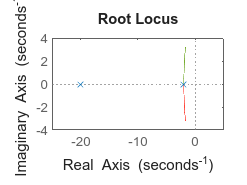


rlocus(Gs, linspace(0,200,1e4))

K = 171

K = 171

KGs = K * Gs


KGs =
 
            171
  ------------------------
  s^3 + 24 s^2 + 84 s + 80
 
Continuous-time transfer function.
Model Properties


tf = KGs/ (1+KGs)


tf =
 
               171 s^3 + 4104 s^2 + 14364 s + 13680
  ---------------------------------------------------------------
  s^6 + 48 s^5 + 744 s^4 + 4363 s^3 + 15000 s^2 + 27804 s + 20080
 
Continuous-time transfer function.
Model Properties


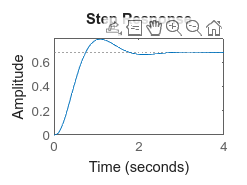

step(tf)

Gcs = (s+1)/s


Gcs =
 
  s + 1
  -----
    s
 
Continuous-time transfer function.
Model Properties


Gcomp = Gcs *Gs


Gcomp =
 
             s + 1
  ----------------------------
  s^4 + 24 s^3 + 84 s^2 + 80 s
 
Continuous-time transfer function.
Model Properties


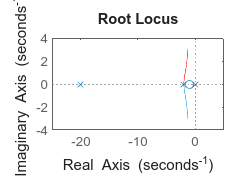

rlocus(Gcomp, linspace(0,200,1e4))

KGcomp = 133*Gcomp


KGcomp =
 
          133 s + 133
  ----------------------------
  s^4 + 24 s^3 + 84 s^2 + 80 s
 
Continuous-time transfer function.
Model Properties


tfcomp = KGcomp / (1+KGcomp)


tfcomp =
 
               133 s^5 + 3325 s^4 + 14364 s^3 + 21812 s^2 + 10640 s
  -------------------------------------------------------------------------------
  s^8 + 48 s^7 + 744 s^6 + 4325 s^5 + 14221 s^4 + 27804 s^3 + 28212 s^2 + 10640 s
 
Continuous-time transfer function.
Model Properties


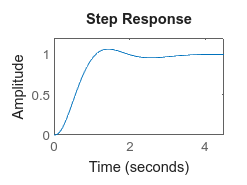

step(tfcomp)

Question 2

clear;
s = tf('s')


s =
 
  s
 
Continuous-time transfer function.
Model Properties


%a
Gs = (s+6) / ((s+2)*(s+3)*(s+5))


Gs =
 
           s + 6
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.
Model Properties


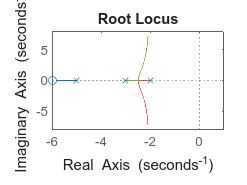

rlocus(Gs,linspace(0,50,1e4))

%b
Gsk = 4.6 * Gs


Gsk =
 
        4.6 s + 27.6
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.
Model Properties


Ts = Gsk / (1+Gsk)


Ts =
 
          4.6 s^4 + 73.6 s^3 + 418.6 s^2 + 993.6 s + 828
  ---------------------------------------------------------------
  s^6 + 20 s^5 + 166.6 s^4 + 753.6 s^3 + 1980 s^2 + 2854 s + 1728
 
Continuous-time transfer function.
Model Properties


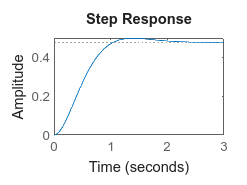

step(Ts)

%c
damp = 0.707

damp = 0.7070

natfreq = 4/(0.8621*damp)

natfreq = 6.5627

rl = damp*natfreq

rl = 4.6398

imag = natfreq * sqrt(1-damp^2)

imag = 4.6412

CLroot = -rl+imag*1j

CLroot = -4.6398 + 4.6412i


checkRootLocusAngle(Gs,CLroot)

ans = struct with fields:
    sum: -240.9860
    mod: 119.0140


theta = 60.99

theta = 60.9900

zeroLoc = (imag + tand(theta)*rl) / (tand(theta))

zeroLoc = 7.2136

Gc = (s+zeroLoc)


Gc =
 
  s + 7.214
 
Continuous-time transfer function.
Model Properties


Gcomp = Gc*Gs


Gcomp =
 
   s^2 + 13.21 s + 43.28
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.
Model Properties


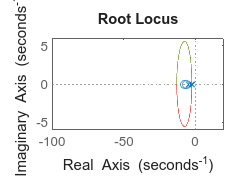

rlocus(Gcomp,linspace(0,100,1e4))

KGcomp = 4.76*Gcomp


KGcomp =
 
  4.76 s^2 + 62.9 s + 206
  ------------------------
  s^3 + 10 s^2 + 31 s + 30
 
Continuous-time transfer function.
Model Properties


tcomp = KGcomp/(1+KGcomp)


tcomp =
 
       4.76 s^5 + 110.5 s^4 + 982.5 s^3 + 4153 s^2 + 8274 s + 6181
  ---------------------------------------------------------------------
  s^6 + 24.76 s^5 + 272.5 s^4 + 1663 s^3 + 5714 s^2 + 1.013e04 s + 7081
 
Continuous-time transfer function.
Model Properties


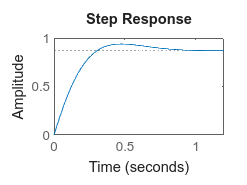

step(tcomp)

kstep = 4.76*43.28/30

kstep = 6.8671

estep = 1/(1+kstep)

estep = 0.1271

Question 3

clear
s= tf('s')

Gsm = 1/(s*(s+2)*(s+5))


Gsm =
 
          1
  ------------------
  s^3 + 7 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


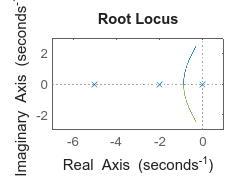

rlocus(Gsm,linspace(0,40,1e4))

damp = 0.69

damp = 0.6900

natfreq= 4/(4*damp)

natfreq = 1.4493

rl = damp*natfreq

rl = 1

imag = natfreq * sqrt(1-damp^2)

imag = 1.0490

clpole = -rl+imag*1j

clpole = -1.0000 + 1.0490i

checkRootLocusAngle(Gsm,clpole)

ans = struct with fields:
    sum: -194.6949
    mod: 165.3051


theta = 14.695

theta = 14.6950

zeroLoc = (imag + tand(theta)*rl) / (tand(theta))

zeroLoc = 5.0000

Gc = s+5 %should be named Hsm maybe


Gc =
 
  s + 5
 
Continuous-time transfer function.
Model Properties


Rloc = Gsm*Gc


Rloc =
 
        s + 5
  ------------------
  s^3 + 7 s^2 + 10 s
 
Continuous-time transfer function.
Model Properties


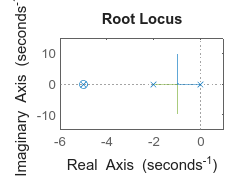

rlocus(Rloc,linspace(0,100, 1e4))

K1 = 2.1

K1 = 2.1000

Tminor = (K1*Gsm)/(1+K1*Gsm*Gc)


Tminor =
 
                 2.1 s^3 + 14.7 s^2 + 21 s
  -------------------------------------------------------
  s^6 + 14 s^5 + 71.1 s^4 + 165.2 s^3 + 194.5 s^2 + 105 s
 
Continuous-time transfer function.
Model Properties


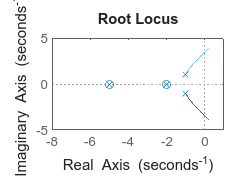

rlocus(Tminor, linspace(0,50,1e4)) 

K=1.12

K = 1.1200

overallTs = K*Tminor/(1+K*Tminor)


overallTs =
 
                             2.352 s^9 + 49.39 s^8 + 421.2 s^7 + 1888 s^6 + 4850 s^5 + 7335 s^4 + 6303 s^3 + 2470 s^2
  -----------------------------------------------------------------------------------------------------------------------------------------------
  s^12 + 28 s^11 + 338.2 s^10 + 2324 s^9 + 1.012e04 s^8 + 2.957e04 s^7 + 5.978e04 s^6 + 8.404e04 s^5 + 7.986e04 s^4 + 4.715e04 s^3 + 1.349e04 s^2
 
Continuous-time transfer function.


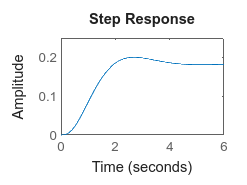

step(overallTs)